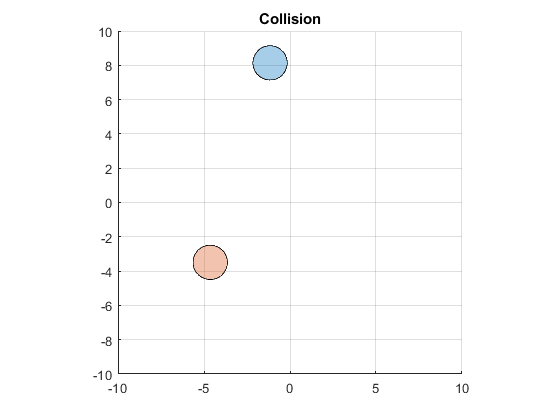

close all
c1 = circle;
c1.polygon = polyshape(c1.xdata,c1.ydata);
c2 = circle;
c2.polygon = polyshape(c2.xdata,c2.ydata);
x = [1 0];
y = [0 1];
trans = zeros(3,2);
[v1,b1,v2,b2,v3,b3] = generateRandomV(3);
for i = linspace(0,3,50)
    c1.polygon = translate(c1.polygon,v1*i/10);
%     f2 = translate(p2,v2*i+b2);
    c2.polygon = translate(c2.polygon,v3*i/10);
    % deteccion de colisiones para el triangulo usando el SAT
%     for j =1:3
%         trans(j,:) = [dot(x,f2.Vertices(j,:)), dot(y,f2.Vertices(j,:))];
%     end
%     p1min = min(trans);
%     p1max = max(trans);
%     if p1min(1,1) <= -10 || p1max(1,1) >= 10
%         title('Collision with x axis triangle')
%         break
%     elseif p1min(1,2) <= -10 || p1max(1,2) >= 10
%         title('Colision with y axis triangle')
%         break
%     end
    % deteccion de clisiones para los circulos
    if detectCollision(c1,c2) == true
        title('Collision')
        break
        
    end
    
    renderer([c1.polygon,c2.polygon])
end

function collision = detectCollision(p1,p2)
    if class(p1) == "circle" && class(p2) == "circle"
        %% pasar a la funcion colision circle vs cirle
        collision = circlevscircle(p1,p2);
    elseif class(p1) == "circle" || class(p2) == "circle"
        %% pasar a la funcion poligono vs circle
        disp('circulo vs poligono')
    else
        % pasar a la funcion poligono vs poligonoS
        disp('poligono vs poligono')
    end
end

